# Example for using the `rmse` function.

Copyright © 2022 Tamas Kis

Define the independent variable.

x = (0:0.5:10)';

Define the true data.

y = x.^2+4+mvnrnd(0,5,length(x));

Estimate the data using a model.

y_hat = x.^2+4;

Determine the root-mean-square error.

RMSE = rmse(y,y_hat)

RMSE = 2.8105

Plot the true and estimated values.

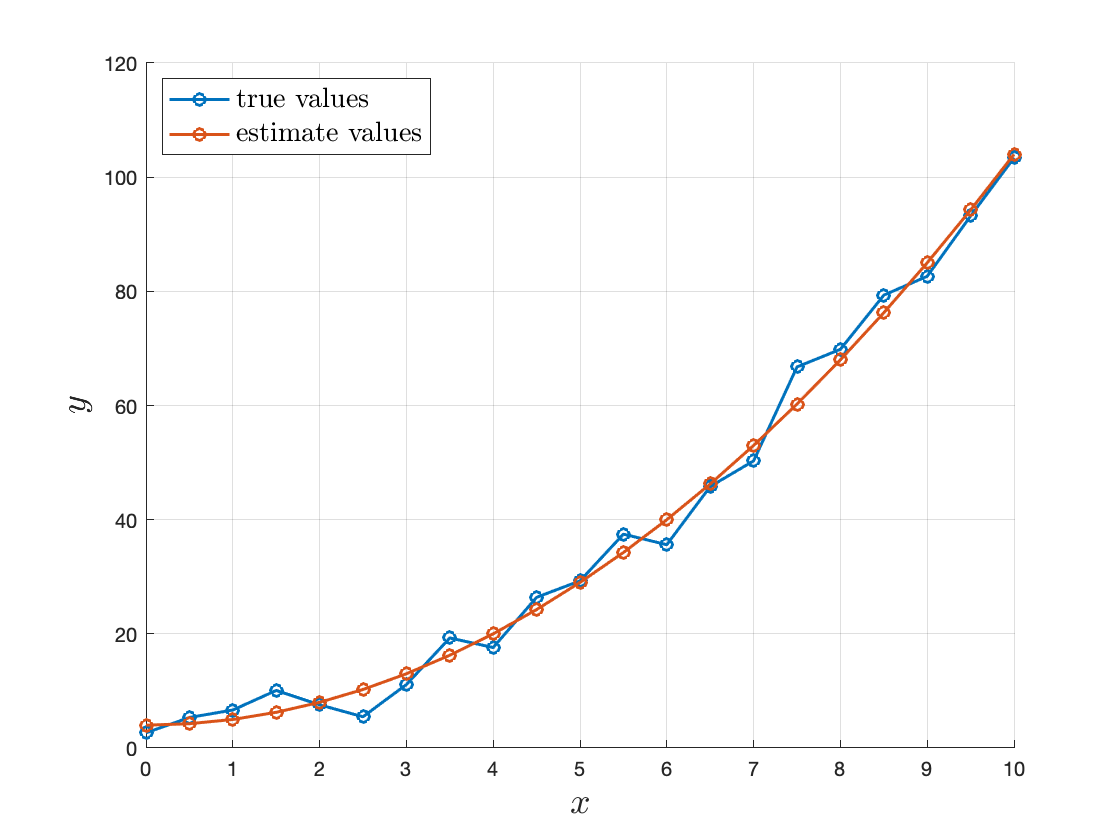

figure;
hold on;
plot(x,y,'-o','LineWidth',1.5);
plot(x,y_hat,'-o','LineWidth',1.5);
grid on;
hold off;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
legend('true values','estimate values','Interpreter','latex','FontSize',14,...
    'Location','northwest');